% (tan(y)-y/sin(x)^2)*dx+(1/tan(x)+x/cos(y)^2)*dy

clear
syms x y dx dy C
eq1=(tan(y)-y/sin(x)^2)*dx+(1/tan(x)+x/cos(y)^2)*dy

$$eq1 = \mathrm{dx}\,\left(\tan\left(y\right)-\frac{y}{{\sin\left(x\right)}^{2}}\right)+\mathrm{dy}\,\left(\frac{x}{{\cos\left(y\right)}^{2}}+\frac{1}{\tan\left(x\right)}\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} \tan\left(y\right)-\frac{y}{{\sin\left(x\right)}^{2}} & \frac{x}{{\cos\left(y\right)}^{2}}+\frac{1}{\tan\left(x\right)} \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = \tan\left(y\right)-\frac{y}{{\sin\left(x\right)}^{2}}$$

$$Q = \frac{x}{{\cos\left(y\right)}^{2}}+\frac{1}{\tan\left(x\right)}$$

f=simplify(diff(Q,x)-diff(P,y))

$$f = 0$$


% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P,x)+C(y)

$$U = C\left(y\right)+\frac{y}{\tan\left(x\right)}+x\,\tan\left(y\right)$$

% C(y) + y/tan(x) + x*tan(y)
dUy=diff(U,y)

$$dUy = \frac{1}{\tan\left(x\right)}+x\,\left({\tan\left(y\right)}^{2}+1\right)+\frac{\partial }{\partial y}C\left(y\right)$$

% 1/tan(x) + x*(tan(y)^2 + 1) + diff(C(y), y)
dCy=simplify(dUy-Q)

$$dCy = \frac{\partial }{\partial y}C\left(y\right)$$

% diff(C(y), y) = 0
% C(y)=C1
% y/tan(x) + x*tan(y) + C1 = 0
U=y/tan(x) + x*tan(y)

$$U = \frac{y}{\tan\left(x\right)}+x\,\tan\left(y\right)$$

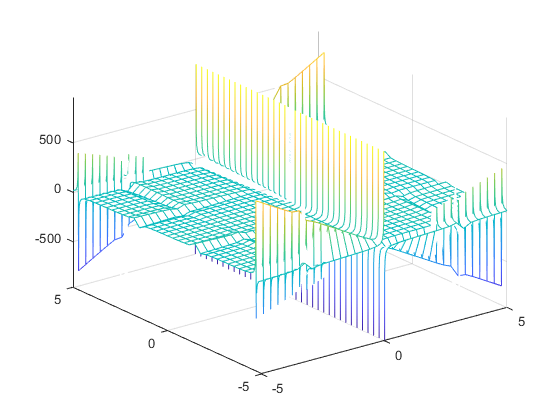

fmesh(U)